## Read image

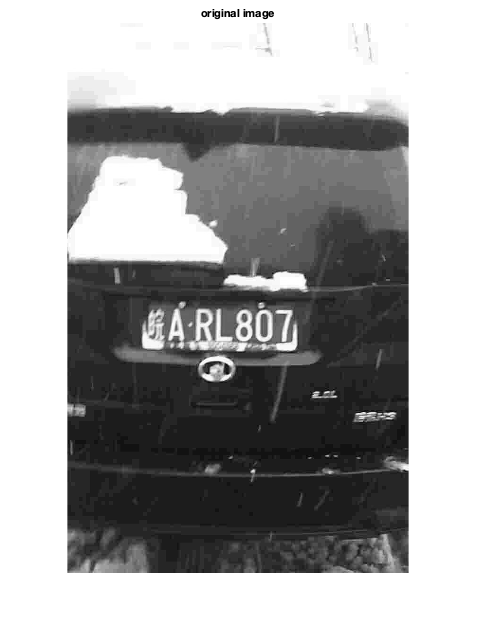

% prompt user to enter image path
% image = input('Enter image path: ');
image = 'images/Snow2.jpg'; % TBD
Iraw = rgb2gray(imread(image)); % read image and convert it to grayscale
[h, w] = size(Iraw);
Iraw = imresize(Iraw, 1024 / w); % rescale image to have width of 1024

figure, imshow(Iraw), title('original image');

## Preprocessing

## Initial cropping

Crop the bottom half of the image if required

% prompt user for yes or no input
crop_bottom = input('Crop bottom half? (y/n): ', 's');
crop_bottom = crop_bottom == 'y';
if crop_bottom
    [h, w] = size(Iraw);
    % "zoom" slightly closer into the image
    Iraw = Iraw(ceil(h*0.05) + 1:floor(end-h*0.05), ceil(w*0.05) + 1:floor(end-w*0.05));
    % crop bottom half of the image
    Iraw = Iraw(floor(h/2):end, :);
    
    figure, imshow(Iraw), title('cropped image');
end

### Detecting number plate region

Detect egdes and fill in the holes to get a mask for number plate

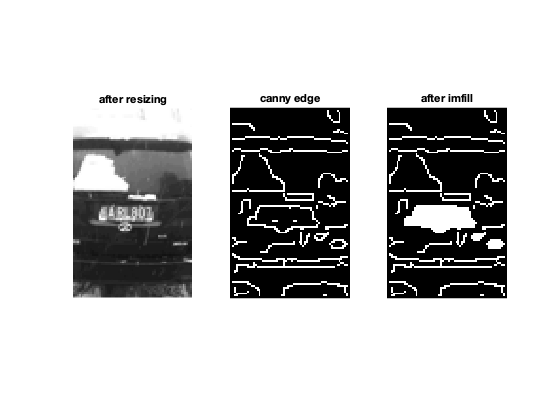

I = Iraw;

% prompt user to enter desired image height after scaling
image_height = str2double(input('Enter image height for edge detection: ', 's'));

% scale image so that it has the same height as user input
[h, w] = size(I);
I = imresize(I, [image_height (w * image_height / h)]);

Ihe = histeq(I); % adjust the contrast 
Icanny = edge(Ihe,'canny'); % canny edge detection
Ifilled = imfill(Icanny, 'holes'); % fill in holes within edges

figure;
subplot(1,3,1), imshow(I), title('after resizing');
subplot(1,3,2), imshow(Icanny), title('canny edge');
subplot(1,3,3), imshow(Ifilled), title('after imfill');

Clean the mask by removing small pieces of edges and holes

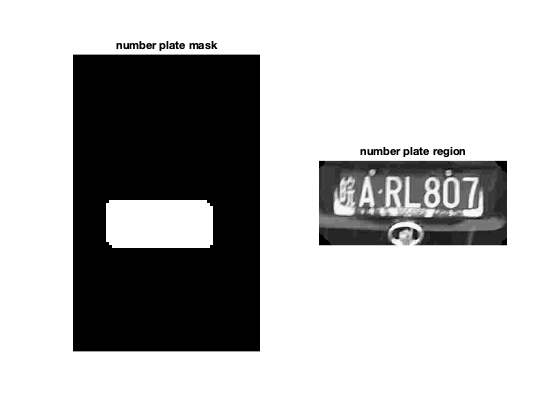

SEdiskSize = 7;
SErectWidth = 30;
notFound = true;

% perform multiple openings to clean the mask
% slowly decrease strutural element size used for opening until a mask is
% found, or the SE has size of 0
while notFound && SEdiskSize > 0
    
    Imask = Ifilled;
    
    % perform opening with disk shaped SE to remove small edge pieces
    SE = strel('disk', SEdiskSize);
    Imask = imopen(Imask, SE);
    
    % perform opening again with rectangular SE
    SE = ones(3, SErectWidth);
    Imask = imopen(Imask, SE);
    
    % dilate to expand the mask in case the surroundings of number plate
    % got missed out
    SE = ones(7, 7);
    Imask = imdilate(Imask, SE);
    
    % get number plate region by multiplying image with mask
    Ifiltered = immultiply(imresize(Imask, size(Iraw)), Iraw);
    
    % remove background (rows/columns that are all black pixels)
    Iplate = Ifiltered;
    Iplate = Iplate(:, ~(sum(Iplate) == 0));
    Iplate = Iplate(~(sum(Iplate, 2) == 0), :);
    
    % check if there is a mask in the image
    if sum(Iplate, 'all') > 0
        notFound = false;
    end
    
    % reduce structuring element size
    SEdiskSize = SEdiskSize - 1;
    SErectWidth = SErectWidth - 4;
end

if notFound
    disp('Number plate detection failed - no mask found')
end

figure;
subplot(1, 2, 1), imshow(Imask), title('number plate mask')
subplot(1, 2, 2), imshow(Iplate), title('number plate region')

### Postprocessing of the car plate region

Convert image to its complement if the number plate background has a lighter color than the characters

% prompt user to enter yes or no input
hasLightBg = input('Number plate has lighter background? (y/n): ', 's');
hasLightBg = hasLightBg == 'y';
if hasLightBg
    Iplate = imcomplement(Iplate); % convert image to its complement
    figure, imshow(Iplate);
end

Straighten the image based on the thetha values of straight lines detected

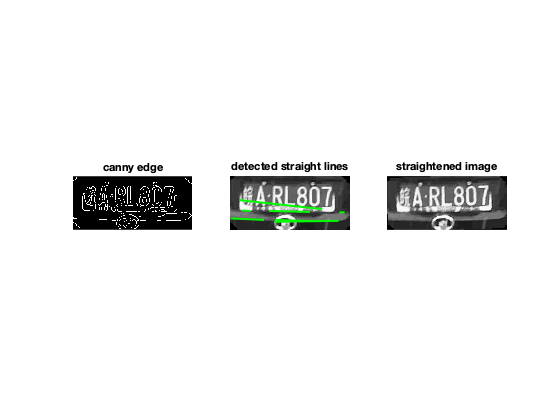

% resize the image
[w, h] = size(Iplate);
newWidth = 256;
IplateResized = imresize(Iplate, [(w * newWidth / h) newWidth]);

% canny edge detection
Icanny2 = edge(IplateResized,'canny');

% compute hough transform and get thetha(T) and rho(R) values
[H, T, R] = hough(Icanny2);
P = houghpeaks(H, 4); % use the highest 4 hough peaks

% get the detected straight lines
lines = houghlines(Icanny2, T, R, P,'FillGap', 20, 'MinLength', 4); 

% get line angles
thethas = [lines.theta];

% ensure angle is always measured in the same direction
thethas(thethas > 0) = thethas(thethas > 0) - 180;

% filter candidate horizontal lines
% exclude lines that are too steep (lines that differ by more than or equal to 
% 20 degrees from the horizontal lines)
idx = find(abs(90 + thethas) < 20);
lines = lines(idx);
thethas = thethas(idx);

% rotate image based on the average angle of horizontal lines
IplateRotated = imrotate(Iplate, 90 + mean(thethas), 'crop');

figure;
subplot(1,3,1), imshow(Icanny2), title('canny edge');
subplot(1,3,2), imshow(IplateResized), title('detected straight lines'), hold on
% show lines detected
for k = 1:length(lines)
    xy = [lines(k).point1; lines(k).point2];
    plot(xy(:,1), xy(:,2), 'LineWidth', 2, 'Color', 'green'); 
end
subplot(1,3,3), imshow(IplateRotated), title('straightened image');

Convert image to binary

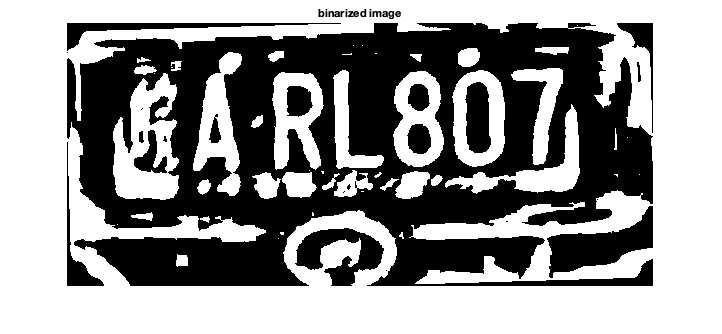

% binarize image
Ibi = IplateRotated;
Ibi = imbinarize(Ibi, 'adaptive');

% prepare image for the next step
% scale image so that it has height of 256
[h, w] = size(Ibi);
newHeight = 256;
Ibi = imresize(Ibi, [newHeight (w * newHeight / h)]);
% ensure there is at least one pixel wide of margin 
% on the top and bottom of the plate
[h, w] = size(Ibi);
margin = zeros(1, w);
Ibi = cat(1, margin, Ibi, margin);

figure; imshow(Ibi), title('binarized image');

### Removing margins around number plate characters

Remove top and bottom margins

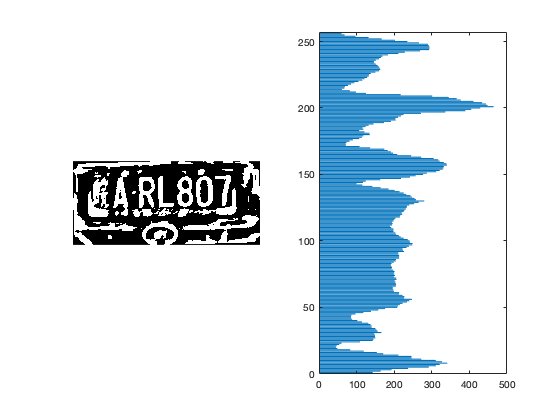

% compute vertical profile by taking the sum of each row
verticalProfile = sum(Ibi, 2);

figure;
subplot(1,2,1); imshow(Ibi);
subplot(1,2,2); barh(verticalProfile); % used to determine VPthreshold

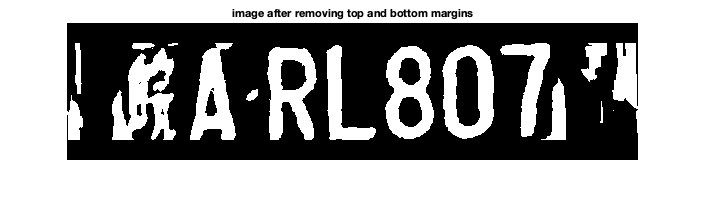

% prompt user for threshold value
% the rows that contains number plate character must have white pixel count above this value
VPthreshold = input('Enter threshold to segment number plate rows: ');

[h, w] = size(Ibi);

% separate the image into segments horizontally at rows that have white pixels below VPthreshold
% assuming the characters consume majority of the space, the row segment 
% with the largest height is a row of characters in the number plate
idx = find(verticalProfile < VPthreshold);
[sortedDiff, argSortedDiff] = sort(diff(idx));    
rowHeight = sortedDiff(end);    

% show warnings if region detected has very low height, which is unlikely
% to be a car plate region
if rowHeight < h * 0.2
    disp('Warning - row height detected is too low, you could consider varying VPthreshold');
end

% get start and end row index
startY = idx(argSortedDiff(end));
endY = idx(argSortedDiff(end) + 1);

% create background pixels as vertical margins
marginLenV = ceil(rowHeight * 0.2);
marginV = zeros(marginLenV, w);

% crop the image using the start and end row index and
% add some margin on top and bottom
IfocusV = cat(1, marginV, Ibi(startY:endY,:), marginV);

% check if there is a second row
% the second row is assumed to have similar height
hasTwoRows = false;
thresh = rowHeight * 0.3;
if sortedDiff(end) - sortedDiff(end-1) < thresh
    
    % get start and end row index
    startY2 = idx(argSortedDiff(end - 1));
    endY2 = idx(argSortedDiff(end - 1) + 1);
    
    % pad the shorter row to have the same height with the taller row
    row2 = cat(1, marginV, Ibi(startY2:endY2,:), marginV);
    [h1, w1] = size(IfocusV);
    [h2, w2] = size(row2);
    row2 = padarray(row2, [(h1 - h2) 0], 0, 'pre');
    
    % check which row comes first and concat them in the correct order with
    % some gap in between
    if startY < startY2
        IfocusV = cat(1, IfocusV, row2, marginV);
    else
        IfocusV = cat(1, marginV, row2, IfocusV);
    end
    hasTwoRows = true;
end

figure;
imshow(IfocusV), title('image after removing top and bottom margins');

Remove left and right margins

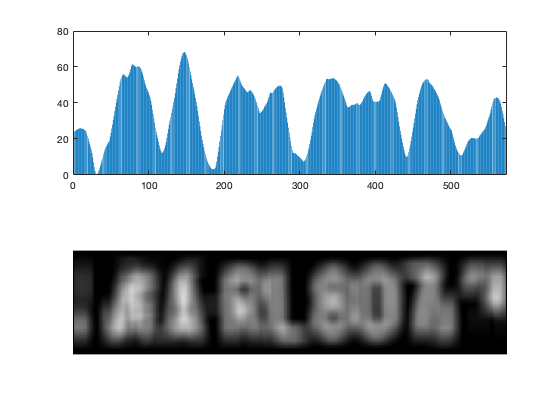

% this step is similar with the previous step, but with a additional
% preprocessing step that blurs the image

% blur image so that there will be white pixels
% connecting each character on the number plate
k = fspecial('gaussian', [30 30], 20);
IfocusVG = imfilter(IfocusV, k);

% ensure that the first and last value of the 
% horizontal profile is 0
[h, w] = size(IfocusV);
marginH = zeros(h, 1);
IfocusVG = cat(2, marginH, IfocusVG, marginH);

% compute horiozontal profile by taking the sum of each column
horizontalProfile = sum(IfocusVG, 1); 

figure;
subplot(2,1,1); bar(horizontalProfile); % used to determine HPthreshold
subplot(2,1,2); imshow(IfocusVG);

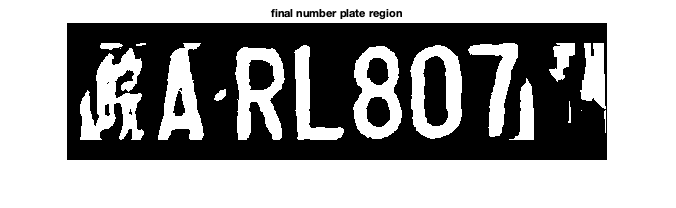

% prompt user for threshold value
% the columns that contains number plate character must have white pixel count above this value
HPthreshold = input('Enter threshold to segment number plate columns: ');

% separate the image into segments vertically at columns that have white pixels below HPthreshold
% the column segment with the largest width is a sequence of characters in the number plate
idx = find(horizontalProfile < HPthreshold);
[sortedDiff, argSortedDiff] = sort(diff(idx));

% get the start and end column index
startX = idx(argSortedDiff(end));
endX = min(idx(argSortedDiff(end) + 1), w);
% crop the image using the start and end column index
IplateFocus = cat(2, marginH, IfocusV(:, startX:endX), marginH);

[h, w] = size(IplateFocus);

% check if there is a second sequence that are not connected to the first
% the second sequence are assumed to have similar width
thresh = w * 0.4;
if sortedDiff(end-1) > thresh
    startX2 = idx(argSortedDiff(end - 1));
    endX2 = idx(argSortedDiff(end - 1) + 1);
    
    % check which sequence comes first and concat the two sequence together
    if startX2 > startX
        IplateFocus = cat(2, IplateFocus, IfocusV(:, startX2:endX2), marginH);    
    else
        IplateFocus = cat(2, marginH, IfocusV(:, startX2:endX2), IplateFocus);
    end
    
end

figure, imshow(IplateFocus), title('final number plate region');

### Rearranging characters layout

If there are two rows of characters in the car plate, combine them into one

IplateFinal = IplateFocus;
[h w] = size(IplateFinal);

if hasTwoRows
 
    % separate the two rows in the middle
    mid = h / 2;
    row1 = IplateFinal(1:mid, :);
    row2 = IplateFinal((mid + 1):end, :);
    
    % concat the two rows side by side into one row
    IplateFinal = cat(2, row1, row2);
    [h, w] = size(IplateFinal);
end

## Outline extraction

Preprocess image for skeletonization

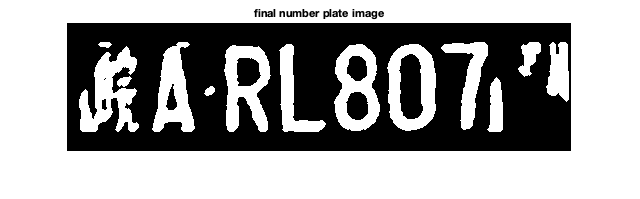

% resize image
IplateFinal = imresize(IplateFinal, [128 floor(w * 128 / h)]);
IplateFinal = imbinarize(IplateFinal);

% opening to remove noises in the background
SE = strel('disk', 2);
IplateFinal = imopen(IplateFinal, SE);

figure; imshow(IplateFinal), title('final number plate image');

Skeletonize image

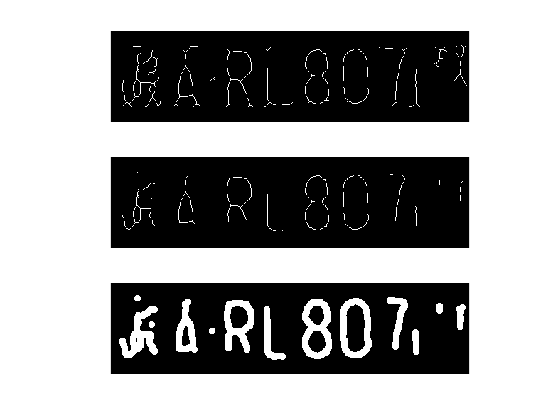

% skeletonize image
IskelImm = bwmorph(IplateFinal, 'skel', Inf);
% prune skeleton
pruneThresh = str2double(input('Enter skeleton pruning threshold: ', 's'));
Iskel = bwmorph(IskelImm, 'spur', pruneThresh);

figure;
subplot(3,1,1), imshow(IskelImm);
subplot(3,1,2), imshow(Iskel);
subplot(3,1,3), imshow (imdilate(Iskel, strel('disk', 3))); % for better visualisation

## Separating characters

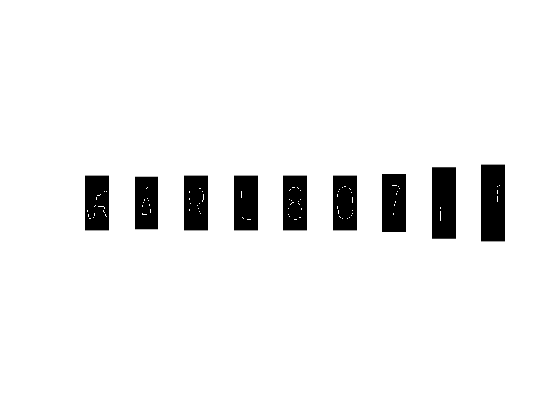

% separate each character by looking at the horizontal profile
horizontalProfile = sum(Iskel, 1); 

% get index of columns that contains white pixel
% we assume those columns to be a part of some character and
% the characters are not connected through any white pixel
argIsChar = find(horizontalProfile > 0);

% get the rightmost index before gap, which is the end column index for
% some character
argEnd = find((diff(argIsChar) ~= 1) == 1);
endIdxs = [argIsChar(argEnd) argIsChar(end)];

% get start column index
startIdxs = [argIsChar(1) argIsChar(argEnd + 1)];

% each segments will have equal width
segmentWidth = ceil(max(endIdxs - startIdxs + 1) * 1.2);

startIdxsF = [];
endIdxsF = [];

% loop through each character segment to filter out segment that contains
% noise pixels only
for i=1:length(startIdxs)
    % only keep segments with more than or equal to 10 white pixels
    if sum(Iskel(:, startIdxs(i):endIdxs(i)), 'all') >= 10
        startIdxsF = [startIdxsF startIdxs(i)];
        endIdxsF = [endIdxsF endIdxs(i)];
    end
end

% show the final output
figure;
n = length(startIdxsF);
for i=1:n
    
    [h w] = size(Iskel);
    
    % margin to pad the characters so each of them have the same width
    % (segmentWidth)
    margin = (segmentWidth - (endIdxsF(i) - startIdxsF(i) + 1)) / 2;
    
    % reduce segment width if there is an overlap with another character
    % segment after adding the left and right margins
    if i == 1
        startMin = 1;
    else
        startMin = endIdxsF(i - 1) + 1;
    end
    if i == n
        endMax = w;
    else
        endMax = startIdxsF(i + 1) - 1;
    end
    
    % compute start and end index after taking the margins into account
    startIdx = max(startIdxsF(i) - ceil(margin), startMin);
    endIdx = min(endIdxsF(i) + floor(margin), endMax);
    
    % extract the character segment
    resSegment = Iskel(:, startIdx:endIdx);
    
    % % uncomment the following code to dilate skeleton for better
    % % visualisation
    % imdilate(resSegment, strel('disk', 3));
    subplot(1,n,i), imshow(resSegment);    
end